# Sinusoid Motion of Chicken Analysis

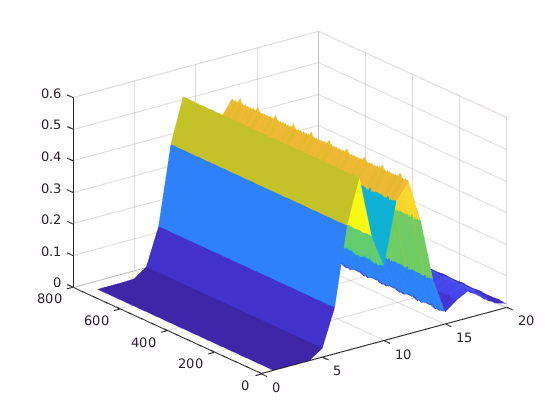

clc
clear
x = linspace(0.0, 9.9, 186);

% Filename
folder = "chicken_water_5";
waveform = "sinusoid";
baseline_n = "baseline-tableonly";
depth = "-1.5cm";
period = "3";
amplitude = "7";
trial = 1;

if (waveform == "sinusoid")
    filename = strcat(folder, "/", waveform, "_D", depth, "_T", ...
        period, "_A", amplitude, "_", num2str(trial), ".mat");
end
if (waveform == "chirp")
    filename = strcat(folder, "/", waveform, "_D", depth, "_A", amplitude, "_", num2str(trial), ".mat");
end
if (waveform == "patient")
    filename = strcat(folder, "/", waveform, "_D", depth, ".mat");
end

%VariableName
dataType = "bb";
dacMIN = "0";
dacMAX = "1400";
frequency = "3";
varName = char(strcat(dataType, dacMIN, "_", dacMAX, "f", frequency));

load(filename, varName);
s_rx = bb0_1400f3;
surf(abs(s_rx(:,1:20)), 'linestyle', 'none');

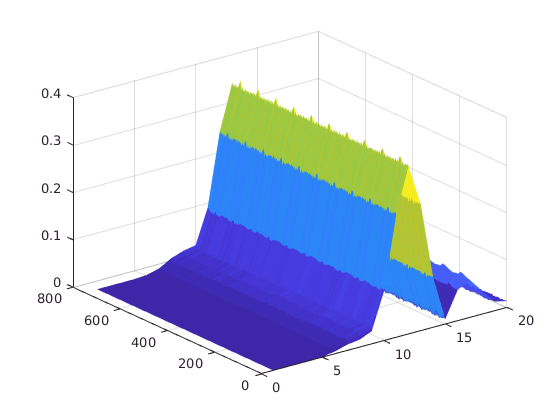


% Subtract baseline
for i = 1:3
   baseline(i) = load(strcat(folder, "/", baseline_n, "_", num2str(i)), varName);
end
baseline_avg = 1/3*(baseline(1).(varName) + baseline(2).(varName) + baseline(3).(varName));

for i = 1:length(s_rx)
    s_rx(i,:) = s_rx(i,:) - baseline_avg;
end

surf(abs(s_rx(:,1:20)), 'linestyle', 'none');


clear amplitude dacMAX dacMIN dataType depth frequency material period trial waveform


## Creating an Input Signal

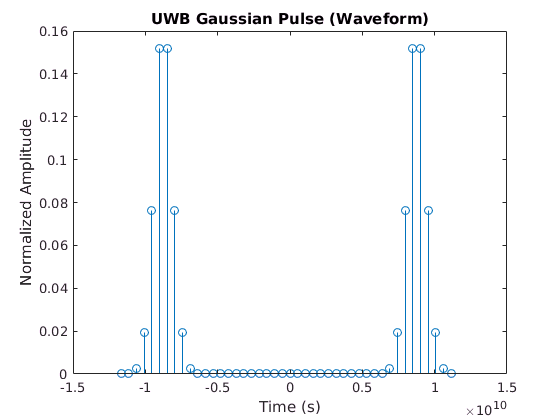

Fs = 23.328e9; % Sampling Frequnecy
Bw = 1.5e9;    % Bandwidth
Fc = 8.748e9;  % Center Frequency

[s_tx, S_tx, t, f] = uwb_wavelet(Fs, Bw, Fc);


clear beta fftPulse L P1 P2 pulse tao tc n


## Use the Match and Downconvert method

% Get the RF values
load(filename, 'rf0_1400f3');
s_rx = rf0_1400f3;

% RF Baseline
for i = 1:3
   baseline_rf(i) = load(strcat(folder, "/", baseline_n, "_", num2str(i)), 'rf0_1400f3');
end
baseline_rf_avg = 1/3*(baseline_rf(1).('rf0_1400f3') + baseline_rf(2).('rf0_1400f3') + baseline_rf(3).('rf0_1400f3'));

% Match and downconvert
chicken_matched_baseline = match_and_downconvert(s_tx, baseline_rf_avg, Fc);

[s_rx_l, ~] = size(s_rx)

s_rx_l = 750

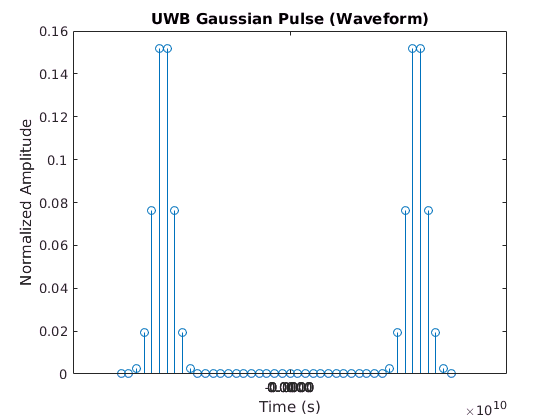

for i = 1:s_rx_l
    chicken_matched(i,:) = match_and_downconvert(s_tx, s_rx(i,:), Fc);
    chicken_matched(i,:) = chicken_matched(i,:) - chicken_matched_baseline;
end 

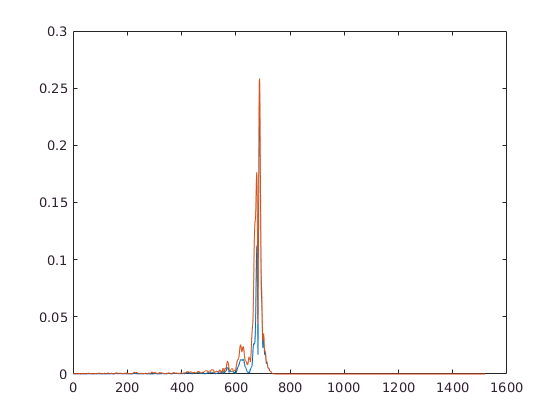

plot(abs(chicken_matched_baseline));
hold on;
plot(abs(chicken_matched(1,:))+ abs(chicken_matched_baseline));
hold off;

% Calibrate with the baseline

t_long = 0:1/25:30-1/25;
t_sample = 0:42.865e-12:42.865e-12*299;

chicken_matched_data = fliplr(chicken_matched(:,1:length(chicken_matched)/2));

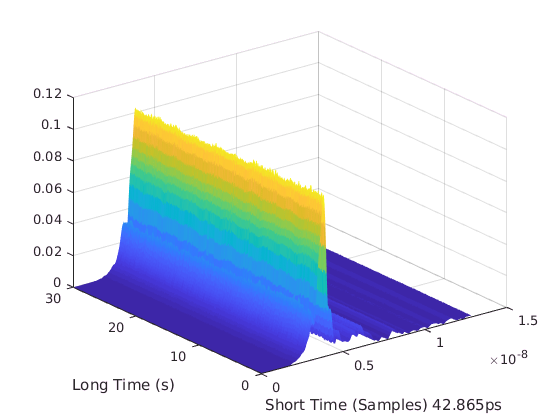

surf(t_sample, t_long, abs(chicken_matched_data(:,1:300)), 'linestyle', 'none');
xlabel('Short Time (Samples) 42.865ps')
ylabel('Long Time (s)')

## Use Motion detection

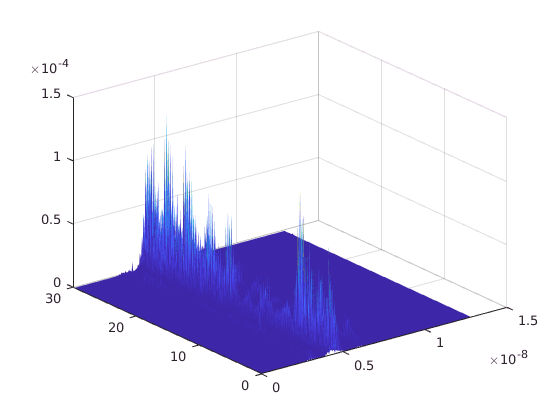

%S_tx_m = motion_detect(s_rx, 5);

Rxy = s_rx;
window = 5;

[Rxy_l, Rxy_w] = size(Rxy);
windows = 1:Rxy_l-window;

S_tx_m = zeros(Rxy_l-window, Rxy_w);
for i = windows
    S_tx_m(i,:) = var(Rxy(i:i+window, :));
end 

surf(t_sample, t_long(1:end-window), S_tx_m(:, 1:300), 'LineStyle', 'None');

xlabel('Short Time (Samples) 42.865ps')
ylabel('Long Time (s)')